# Modelo depredador presa

## Euler

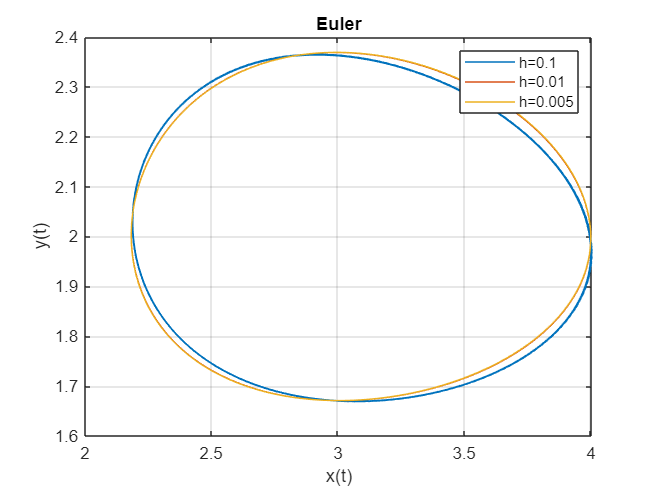


clear all, clc

%===========INPUT================
fx = @(x,y) x*(3-1.5*y);
fy = @(x,y) -y+(1/3)*x*y;

%Condiciones iniciales 
x0 = 4;
y0 = 2;

inter = [0;30];
H = [0.1,0.01,0.005];

%===========OUTPUT================
figure
for h=1:length(H)
    Z = f_eulerd2(fx,fy,[x0;y0],inter,H(h));
    plot(Z(1,1:length(Z)),Z(2,1:length(Z)));
    hold on
end
grid on
legend('h=0.1','h=0.01','h=0.005')
xlabel('x(t)')
ylabel('y(t)')
title('Euler')
hold off 

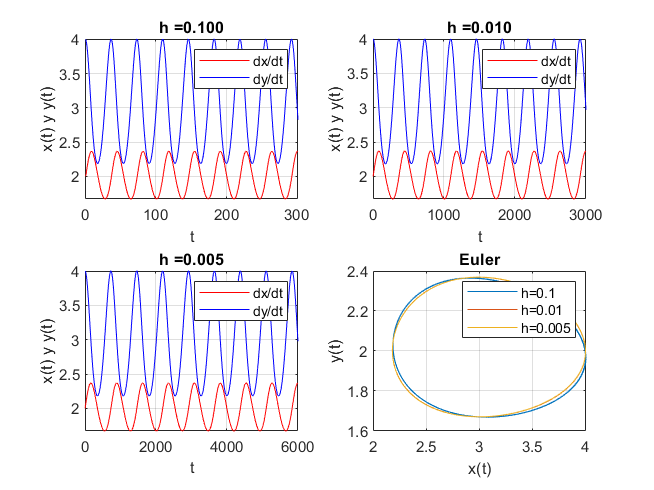


% x(t) e y(t)
figure
for h=1:length(H)
    Z = f_eulerd2(fx,fy,[x0;y0],inter,H(h));
    titulo = strcat('h = ',' ',sprintf('%.3f',H(h)));
    subplot(2,2,h),plot(Z(2,1:length(Z)),'r'),title(titulo);
    hold on
    subplot(2,2,h),plot(Z(1,1:length(Z)),'b'),title(titulo);
    legend('dx/dt','dy/dt')
    xlabel('t')
    ylabel('x(t) y y(t)')
    hold on
    grid on
end

 %Pequeñas modificaciones para que se muestre tambien y(t) con x(t) en el
 %grid
for h=1:length(H)
    Z = f_eulerd2(fx,fy,[x0;y0],inter,H(h));
    subplot(2,2,4),plot(Z(1,1:length(Z)),Z(2,1:length(Z)));
    hold on
end
grid on
legend('h=0.1','h=0.01','h=0.005')
xlabel('x(t)')
ylabel('y(t)')
title('Euler')
hold off 

hold off

## Runge-Kutta

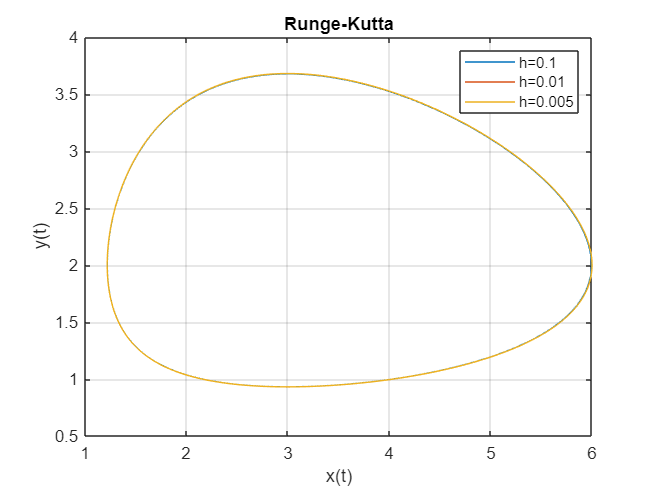


clear all, clc

%===========INPUT================
fx = @(x,y) x*(1-0.5*y);
fy = @(x,y)  y*(-0.75 + 0.25*x);

%Condiciones iniciales 
x0 = 6;
y0 = 2;

inter = [0;30];
H = [0.1,0.01,0.005];

%===========OUTPUT================
figure
for h=1:length(H)
    Z = f_runge_kuttad2(fx,fy,[x0;y0],inter,H(h));
    plot(Z(1,1:length(Z)),Z(2,1:length(Z)));
    hold on
end
grid on
legend('h=0.1','h=0.01','h=0.005')
xlabel('x(t)')
ylabel('y(t)')
title('Runge-Kutta')
hold off 

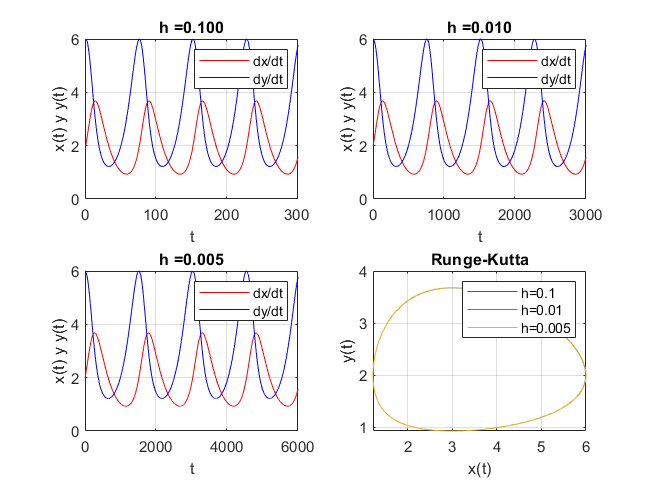


figure
for h=1:length(H)
    Z = f_runge_kuttad2(fx,fy,[x0;y0],inter,H(h));
    titulo = strcat('h = ',' ',sprintf('%.3f',H(h)));
    subplot(2,2,h),plot(Z(2,1:length(Z)),'r'),title(titulo);
    hold on
    subplot(2,2,h),plot(Z(1,1:length(Z)),'b'),title(titulo);
    hold on
    legend('dx/dt','dy/dt')
    xlabel('t')
    ylabel('x(t) y y(t)')
    grid on
end
 %Pequeñas modificaciones para que se muestre tambien y(t) con x(t) en el
 %grid
for h=1:length(H)
    Z = f_runge_kuttad2(fx,fy,[x0;y0],inter,H(h));
    subplot(2,2,4),plot(Z(1,1:length(Z)),Z(2,1:length(Z)));
    hold on
end
grid on
legend('h=0.1','h=0.01','h=0.005')
xlabel('x(t)')
ylabel('y(t)')
title('Runge-Kutta')
hold off 
hold off